% Clear workspace and command window (optional but recommended)
clear; clc;

% Define Parameters
filename = 'amersfoort_heat_demand.csv';
T_hot = 90;           % Supply temperature [°C]
T_cold = 60;          % Return temperature [°C]
rho = 1000;           % Density [kg/m^3]
cp = 4180;            % Specific heat capacity [J/kgK]
delta_T = T_hot - T_cold; 

% Import Data
Demand = readtable(filename);
hour = (1:height(Demand))';
Input = table(hour);

% Convert Heat Demand from Joules to kW
% (Assuming 1 hour timesteps: J/3.6e6 = kWh/h = kW)
Input.Heat_Demand_kW = Demand.Heat_Demand_J / 3.6e6;

% Calculate important statistics
maxHeat = max(Input.Heat_Demand_kW);
minHeat = min(Input.Heat_Demand_kW);
totalHeat = sum(Input.Heat_Demand_kW);
avgHeat = mean(Input.Heat_Demand_kW);
    
% Output Maximum and Minimum Heat generated
fprintf('Maximum Heat Demand: %.2f kW\n', maxHeat);

Maximum Heat Demand: 330171.61 kW


fprintf('Minimum Heat Demand: %.2f kW\n', minHeat);

Minimum Heat Demand: 4350.35 kW


fprintf('Total Heat Demand:   %.2f kW\n', totalHeat); % Note: If summing kW over hours, unit is kWh

Total Heat Demand:   757169022.22 kW


fprintf('Average Heat Demand: %.2f kW\n', avgHeat);

Average Heat Demand: 86434.82 kW


% --- Energy Calculations ---
Input.supply_kW = avgHeat * ones(height(Input), 1);

% Calculate the difference (Net Flow)
% Positive = Surplus (Charge), Negative = Deficit (Discharge)
difference = Input.supply_kW - Input.Heat_Demand_kW;
net_flow = difference;

% Split into Save/Take for clarity
Input.Save_To_Storage = max(difference, 0);
Input.Take_From_Storage = min(difference, 0);

% Calculate Cumulative Energy Stored
Input.Total_Stored = cumsum(net_flow);

% Shift Energy Storage to ensure it never drops below zero
minEnergy = min(Input.Total_Stored);
if minEnergy < 0
    Input.Total_Stored_shifted = Input.Total_Stored + abs(minEnergy);
else
    Input.Total_Stored_shifted = Input.Total_Stored; 
end

% --- Volume Calculations ---
% Calculate Volume Flow Rate [m^3/h]
% Formula: Q [kW] * 1000 [W/kW] * 3600 [s/h] / (rho * cp * dT)
Input.Volume_flows = net_flow * 1000 * 3600 / (rho * cp * delta_T); 

% Calculate Cumulative Volume Stored
Input.Volume_stored = cumsum(Input.Volume_flows); 

% Shift Volume Storage to ensure it never drops below zero
minVolume = min(Input.Volume_stored);
if minVolume < 0
    Input.Volume_Stored_shifted = Input.Volume_stored + abs(minVolume);
else
    Input.Volume_Stored_shifted = Input.Volume_stored; 
end

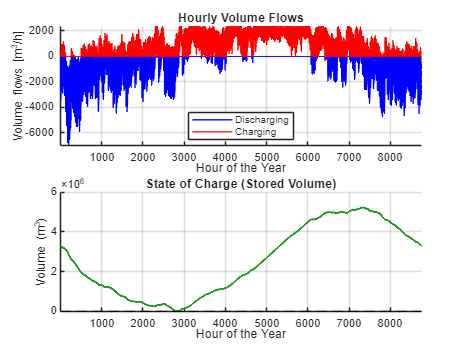

figure('Name', 'Volume Analysis', 'Position', [100, 100, 800, 600]);

% PLOT 1: Volume Flows (Charging vs Discharging)
subplot(2, 1, 1);
hold on; grid on;
charging_volume = max(Input.Volume_flows, 0);
discharging_volume = min(Input.Volume_flows, 0);

plot(Input.hour, discharging_volume, 'b-', 'LineWidth', 1, 'DisplayName', 'Discharging');
plot(Input.hour, charging_volume, 'r-', 'LineWidth', 1, 'DisplayName', 'Charging');

title('Hourly Volume Flows');
xlabel('Hour of the Year');
ylabel('Volume flows [m^3/h]');
legend('Location', 'best');
xlim([1 height(Input)]);

% PLOT 2: State of Charge (Volume)
subplot(2, 1, 2);
hold on; grid on;

plot(Input.hour, Input.Volume_Stored_shifted, 'Color', [0.1 0.6 0.1], 'LineWidth', 1.5);
yline(0, 'k--', 'LineWidth', 1); % Zero reference

title('State of Charge (Stored Volume)');
xlabel('Hour of the Year');
ylabel('Volume (m^3)'); 
xlim([1 height(Input)]);

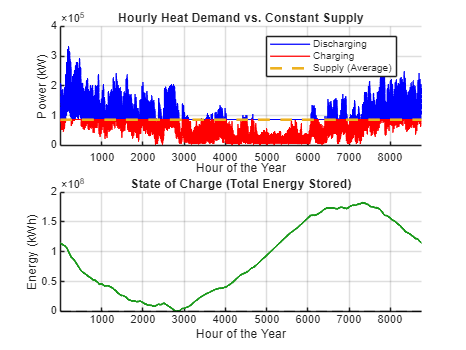

figure('Name', 'Energy Analysis', 'Position', [150, 150, 800, 600]);

% PLOT 1: Power Balance
subplot(2, 1, 1);
hold on; grid on;

% Visualize Discharging (Demand > Supply) and Charging (Supply > Demand) relative to avg
plot(Input.hour, -Input.Take_From_Storage + avgHeat, 'b-', 'LineWidth', 1, 'DisplayName', 'Discharging');
plot(Input.hour, -Input.Save_To_Storage + avgHeat, 'r-', 'LineWidth', 1, 'DisplayName', 'Charging');
plot(Input.hour, Input.supply_kW, '--', 'LineWidth', 2, 'DisplayName', 'Supply (Average)');

title('Hourly Heat Demand vs. Constant Supply');
xlabel('Hour of the Year');
ylabel('Power (kW)');
legend('Location', 'best');
xlim([1 height(Input)]);

% PLOT 2: State of Charge (Energy)
subplot(2, 1, 2);
hold on; grid on;

plot(Input.hour, Input.Total_Stored_shifted, 'Color', [0.1 0.6 0.1], 'LineWidth', 1.5);
yline(0, 'k--', 'LineWidth', 1);

title('State of Charge (Total Energy Stored)');
xlabel('Hour of the Year');
ylabel('Energy (kWh)'); 
xlim([1 height(Input)]);

%% --- RECALCULATE WITH HEAT LOSSES ---

% 1. Estimate Tank Geometry (Assume a Cylinder where Height = 2 * Radius)
% Volume = pi * r^2 * h  ->  Volume = 2 * pi * r^3
Ideal_Max_Vol = max(Input.Volume_Stored_shifted); 
radius = (Ideal_Max_Vol / (2 * pi))^(1/3);
height_tank = 2 * radius;

% Calculate Surface Area (Top + Bottom + Sides)
Surface_Area = (2 * pi * radius^2) + (2 * pi * radius * height_tank);

% 2. Define Loss Parameters
U_value = 0.5; % W/m^2K (Insulation quality)
T_env = 10;    % °C (Ground or Air temperature)
Loss_Watts = U_value * Surface_Area * (T_hot - T_env);
Loss_kW = Loss_Watts / 1000;

fprintf('\n--- Heat Loss Calculation ---\n');


--- Heat Loss Calculation ---


fprintf('Estimated Tank Radius: %.2f m\n', radius);

Estimated Tank Radius: 94.07 m


fprintf('Constant Heat Loss:    %.2f kW\n', Loss_kW);

Constant Heat Loss:    6671.92 kW



% 3. Apply Losses to the Flow
% We subtract the loss from the net_flow (Supply - Demand - Loss)
net_flow_with_loss = Input.supply_kW - Input.Heat_Demand_kW - Loss_kW;

% 4. Recalculate Storage
Input.Volume_flows_loss = net_flow_with_loss * 1000 * 3600 / (rho * cp * delta_T);
Input.Volume_stored_loss = cumsum(Input.Volume_flows_loss);

% Shift the new storage curve
minVolume_loss = min(Input.Volume_stored_loss);
if minVolume_loss < 0
    Input.Volume_Real = Input.Volume_stored_loss + abs(minVolume_loss);
else
    Input.Volume_Real = Input.Volume_stored_loss;
end

% Check the new Max Volume required
fprintf('New Max Volume (with losses): %.2f m^3\n', max(Input.Volume_Real));

New Max Volume (with losses): 4365606.53 m^3


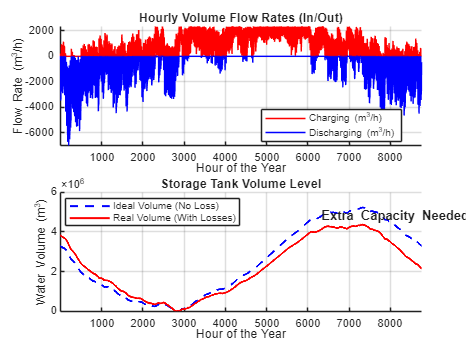

figure('Name', 'Storage Volume Analysis', 'Position', [150, 150, 800, 600]);

% --- PLOT 1: Volume Flow Rates (m^3/h) ---
subplot(2, 1, 1);
hold on; grid on;

% Separate flows into Charging (+) and Discharging (-) for visualization
% Note: Volume_flows is correctly in m^3/h from your previous calculation
Charging_Flow = max(Input.Volume_flows, 0);
Discharging_Flow = min(Input.Volume_flows, 0);

% Plot Area or Line - Line is cleaner for 8760 points
plot(Input.hour, Charging_Flow, 'r-', 'LineWidth', 0.5, 'DisplayName', 'Charging (m^3/h)');
plot(Input.hour, Discharging_Flow, 'b-', 'LineWidth', 0.5, 'DisplayName', 'Discharging (m^3/h)');
%yline(0, 'k-', 'LineWidth', 1);

title('Hourly Volume Flow Rates (In/Out)');
xlabel('Hour of the Year');
ylabel('Flow Rate (m^3/h)');
legend('Location', 'best');
xlim([1 height(Input)]);


% --- PLOT 2: Volume Stored (State of Charge in m^3) ---
subplot(2, 1, 2);
hold on; grid on;

% Plot Ideal (No Loss)
plot(Input.hour, Input.Volume_Stored_shifted, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Ideal Volume (No Loss)');

% Plot Real (With Loss) - Assuming you ran the previous heat loss code
if exist('Input', 'var') && ismember('Volume_Real', Input.Properties.VariableNames)
    plot(Input.hour, Input.Volume_Real, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Real Volume (With Losses)');
    
    % Highlight the extra volume needed
    max_ideal = max(Input.Volume_Stored_shifted);
    max_real = max(Input.Volume_Real);
    x_pos = height(Input) * 0.7; % Position text near the end
    text(x_pos, max_real, sprintf(' Extra Capacity Needed: %.0f m^3', max_real - max_ideal), ...
         'VerticalAlignment', 'bottom', 'FontSize', 10, 'FontWeight', 'bold');
else
    text(100, 0, 'Run Heat Loss code first to see the Red line!', 'Color', 'r');
end

%yline(0, 'k-', 'LineWidth', 1);

title('Storage Tank Volume Level');
xlabel('Hour of the Year');
ylabel('Water Volume (m^3)');
legend('Location', 'best');
xlim([1 height(Input)]);